# Taxi Deployment 

## Data Exploration and Preparation 

The first step is to define zones for the taxi deployment. The code below defines three taxi deployment zones in the NYC area. After you are done with your project, feel free to modify these or add your own zones and experiment further. 

Names = ["Manhattan"; ...
         "LaGuardia"; ...
         "JFK"];
 Lat1 = [40.7485;40.766;40.639];
 Lat2 = [40.7576;40.776;40.650];
 Lon1 = [-73.9955;-73.876;-73.793];
 Lon2 = [-73.9773;-73.861;-73.775]; 
pickupLocations = table(Names,Lat1,Lat2,Lon1,Lon2)

pickupLocations = 3×5 table
       Names        Lat1      Lat2      Lon1       Lon2  
    ___________    ______    ______    _______    _______

    "Manhattan"    40.748    40.758    -73.996    -73.977
    "LaGuardia"    40.766    40.776    -73.876    -73.861
    "JFK"          40.639     40.65    -73.793    -73.775


Use the custom function `viewPickupBoxes` to show the zones on a map. 

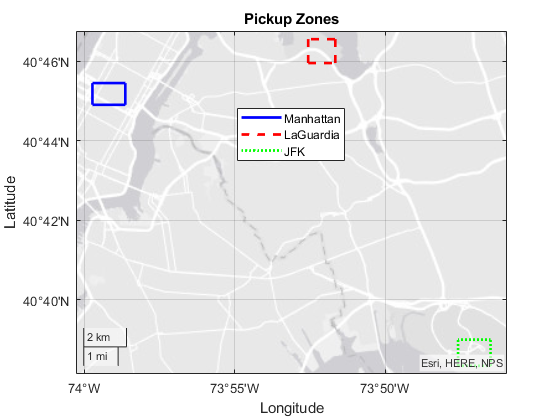

viewPickupBoxes(pickupLocations); 
title('Pickup Zones')

The next step is to create a datastore for the full year of taxi data. Edit the variable `myDataPath` below to reflect where your copy of the taxi data is saved, for or example: 

myDataPath = "C:\Users\samjones\MATLAB Drive\Coursera\Predictive Modeling and Machine Learning\Course Files\Taxi Data";

ds = fileDatastore( myDataPath + "\yellow*.csv","ReadFcn",@importTaxiData,"UniformRead",true);


Finally, the code below uses a custom function `getTaxiPickupData` to count pickups in the zones above over one hour intervals. **Note: **This code may take a while to finish. 

taxiPickups = getTaxiPickupData(ds,60,pickupLocations)

Finished file
Finished file
Finished file
Finished file
Finished file
Finished file
Finished file
Finished file
Finished file
Finished file
Finished file
Finished file


taxiPickups = 26226×3 table
         PickupTime         Location     TripCount
    ____________________    _________    _________

    01-Jan-2015 00:00:00    Manhattan       22    
    01-Jan-2015 00:00:00    LaGuardia        2    
    01-Jan-2015 00:00:00    JFK              2    
    01-Jan-2015 01:00:00    Manhattan       10    
    01-Jan-2015 01:00:00    LaGuardia        0    
    01-Jan-2015 01:00:00    JFK              2    
    01-Jan-2015 02:00:00    Manhattan       14    
    01-Jan-2015 02:00:00    LaGuardia        0    
    01-Jan-2015 02:00:00    JFK              0    
    01-Jan-2015 03:00:00    Manhattan        9    
    01-Jan-2015 03:00:00    LaGuardia        0    
    01-Jan-2015 03:00:00    JFK              0    
    01-Jan-2015 04:00:00    Manhattan       10    
    01-Jan-2015 04:00:00    LaGuardia        1    
    01-Jan-2015 04:00:00    JFK              0    
  

%save taxiPickupData taxiPickups pickupLocations

Error using save
Unable to write file taxiPickupData: permission denied.

If you have already run the previous section to save the data, you may uncomment the line of code below and run this section to load the saved data. 

% load taxiPickupData

### Visualization and Analysis

Analyze the data in the `taxiPickups` table. At a minimum, make sure to provide a visualization of the distribution of the response variable `TripCount `overall, as well as grouped by `Location`, along with some additional analysis of the data in the form of summary stats or further visualizations. 

taxiPickups

taxiPickups = 26226×3 table
         PickupTime         Location     TripCount
    ____________________    _________    _________

    01-Jan-2015 00:00:00    Manhattan       22    
    01-Jan-2015 00:00:00    LaGuardia        2    
    01-Jan-2015 00:00:00    JFK              2    
    01-Jan-2015 01:00:00    Manhattan       10    
    01-Jan-2015 01:00:00    LaGuardia        0    
    01-Jan-2015 01:00:00    JFK              2    
    01-Jan-2015 02:00:00    Manhattan       14    
    01-Jan-2015 02:00:00    LaGuardia        0    
    01-Jan-2015 02:00:00    JFK              0    
    01-Jan-2015 03:00:00    Manhattan        9    
    01-Jan-2015 03:00:00    LaGuardia        0    
    01-Jan-2015 03:00:00    JFK              0    
    01-Jan-2015 04:00:00    Manhattan       10    
    01-Jan-2015 04:00:00    LaGuardia        1    
    01-Jan-2015 04:00:00    JFK              0    
  

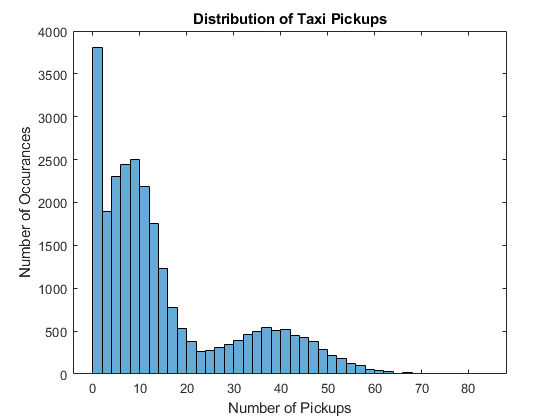

histogram(taxiPickups.TripCount)
title("Distribution of Taxi Pickups")
xlabel("Number of Pickups")
ylabel("Number of Occurances")

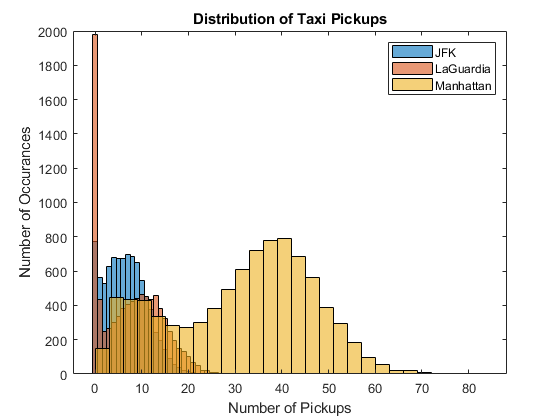

histogram(taxiPickups.TripCount(taxiPickups.Location=="JFK"))
hold on
histogram(taxiPickups.TripCount(taxiPickups.Location=="LaGuardia"))
histogram(taxiPickups.TripCount(taxiPickups.Location=="Manhattan"))
hold off
title("Distribution of Taxi Pickups")
xlabel("Number of Pickups")
ylabel("Number of Occurances")
legend("JFK", "LaGuardia", "Manhattan")

summary(taxiPickups)

Variables:

    PickupTime: 26226×1 datetime

        Values:

            Min       01-Jan-2015 00:00:00
            Median    02-Jul-2015 15:30:00
            Max       31-Dec-2015 23:00:00

    Location: 26226×1 categorical

        Values:

            Manhattan      8742  
            LaGuardia      8742  
            JFK            8742  

    TripCount: 26226×1 double

        Values:

            Min           0   
            Median       10   
            Max          84   



### Separate Test Data 

Use `cvpartition` to separate 20% of the 60 minute interval data set for testing later on, and create the training data. Ensure your results are repeatable. Provide your code. 

rng(1);

taxiPartitions = cvpartition(height(taxiPickups),"HoldOut",0.2);
taxiTest = taxiPickups(taxiPartitions.test,:);
taxiTrain = taxiPickups(taxiPartitions.training,:); 

## Models Training and Validation 

### Baseline Model Training

Preprocess the data (using **providedPreprocessing.mlx**) and train a "Coarse Tree" (Minimum Leaf Size 36) to predict `TripCount`. Use 20% holdout validation. Show your code or screenshot(s) of the training app. Report at least the $RMSE$ and $R^2$ validation metrics, as well as the properties of your final regression tree model (i.e. the output of just the model name without a semicolon). 

taxiTrain = providedPreprocessing(taxiTrain);

ctModel

ctModel = struct with fields:
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'DayOfMonth'  'DayOfWeek'  'DayOfYear'  'Location'  'TimeOfDay'}
       RegressionTree: [1×1 RegressionTree]
                About: 'This struct is a trained model exported from Regression Learner R2020a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


yActual = taxiTrain.TripCount;
yPredicted = ctModel.predictFcn(taxiTrain);
residuals = yActual - yPredicted;
trainMetrics = rMetrics(yActual, yPredicted)

trainMetrics = 1×4 table
     mae       mse       rmse      Rsq  
    ______    ______    ______    ______

    3.1859    22.382    4.7309    0.8989


### Additional Model Training

Train at least one optimized ensemble model to predict `TripCount`.  Show your code or screenshot(s) of the training app. Report at least the $RMSE$ and $R^2$ validation metrics, as well as the properties of your final model (e.g. the output of just the model name without a semicolon). 

optModel

optModel = struct with fields:
                          predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
                   RequiredVariables: {'DayOfMonth'  'DayOfWeek'  'DayOfYear'  'Location'  'TimeOfDay'}
                  RegressionEnsemble: [1×1 classreg.learning.regr.RegressionBaggedEnsemble]
    HyperParameterOptimizationResult: [1×1 BayesianOptimization]
                               About: 'This struct is a trained model exported from Regression Learner R2020a.'
                        HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see 

yActual = taxiTrain.TripCount;
yPredicted = optModel.predictFcn(taxiTrain);
%residuals = yActual - yPredicted;
trainMetrics = rMetrics(yActual, yPredicted)

trainMetrics = 1×4 table
     mae       mse       rmse       Rsq  
    ______    ______    ______    _______

    2.5991    14.484    3.8058    0.93457


## Model Testing and Evaluation 

### Testing

Prepare the test data as needed, and use it to test the baseline tree model as well as at least one additional model. Provide your code and report at least the $RMSE$ and $R^2$ for each. 

%taxiTest = providedPreprocessing(taxiTest);

yActual_1 = taxiTest.TripCount;
yPredicted_1 = ctModel.predictFcn(taxiTest);
residuals_1 = yActual_1 - yPredicted_1;
testMetrics_1 = rMetrics(yActual_1, yPredicted_1)

testMetrics_1 = 1×4 table
     mae       mse       rmse       Rsq  
    ______    ______    ______    _______

    3.4009    25.426    5.0425    0.88611


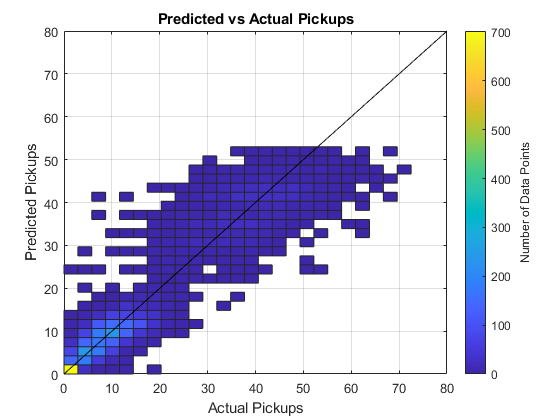

histogram2(yActual_1, yPredicted_1, 25, "DisplayStyle","tile")
line([0 80], [0 80], "Color", "k")
xlabel("Actual Pickups")
ylabel("Predicted Pickups")
title("Predicted vs Actual Pickups")
cb = colorbar();
cb.Label.String = "Number of Data Points";

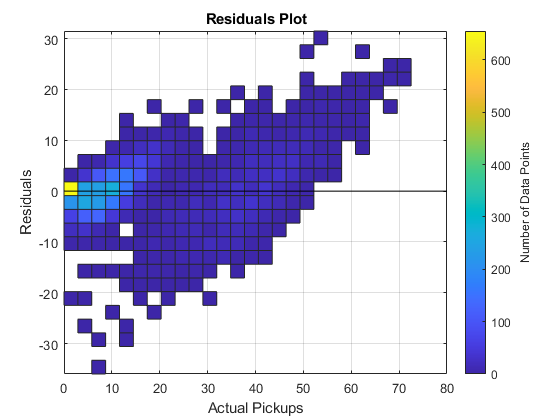

histogram2(yActual_1, residuals_1, 25, "DisplayStyle","tile")
line([0 80], [0 0], "Color", "k")
xlabel("Actual Pickups")
ylabel("Residuals")
title("Residuals Plot")
cb = colorbar();
cb.Label.String = "Number of Data Points";


yActual_2 = taxiTest.TripCount;
yPredicted_2 = optModel.predictFcn(taxiTest);
residuals_2 = yActual_2 - yPredicted_2;
testMetrics_2 = rMetrics(yActual_2, yPredicted_2)

testMetrics_2 = 1×4 table
     mae       mse      rmse       Rsq  
    ______    ______    _____    _______

    3.2293    21.604    4.648    0.90323


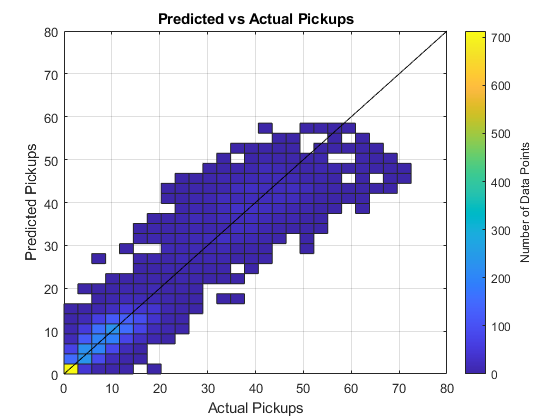


histogram2(yActual_2, yPredicted_2, 25, "DisplayStyle","tile")
line([0 80], [0 80], "Color", "k")
xlabel("Actual Pickups")
ylabel("Predicted Pickups")
title("Predicted vs Actual Pickups")
cb = colorbar();
cb.Label.String = "Number of Data Points";

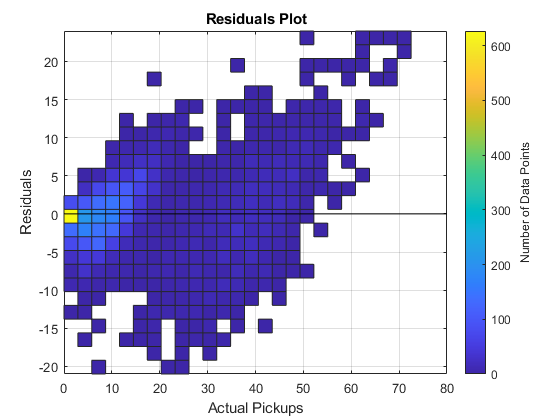

histogram2(yActual_2, residuals_2, 25, "DisplayStyle","tile")
line([0 80], [0 0], "Color", "k")
xlabel("Actual Pickups")
ylabel("Residuals")
title("Residuals Plot")
cb = colorbar();
cb.Label.String = "Number of Data Points";

### Evaluation

Compare the performance of your models. In addition to the metrics, include at least one visual comparison, and a brief discussion of the results. 

## Model Application, Results, and Analysis

### Apply Model 

Choose your favorite day in 2016, then update the features as needed, and *use at least one of your models to predict* `TripCount` for that day in 2016. (Hint: one way to get started is to extract the original 2015 features `PickupTime `and `Location `into a new table, and add a year duration to `PickupTime`.) 

taxiPickups.PickupTime = taxiPickups.PickupTime + years(1);
taxiPickups = providedPreprocessing(taxiPickups);
myDay = datetime(2016,7,4);

taxiPickups.newPickups = optModel.predictFcn(taxiPickups)

taxiPickups = 26226×8 table
         PickupTime         Location     TripCount    TimeOfDay    DayOfWeek    DayOfMonth    DayOfYear    newPickups
    ____________________    _________    _________    _________    _________    __________    _________    __________

    01-Jan-2020 05:06:00    Manhattan       22           5.1       Wednesday        1             1          8.9969  
    01-Jan-2020 05:06:00    LaGuardia        2           5.1       Wednesday        1             1         0.21328  
    01-Jan-2020 05:06:00    JFK              2           5.1       Wednesday        1             1          3.7323  
    01-Jan-2020 06:06:00    Manhattan       10           6.1       Wednesday        1             1          

table(myPickups)
%taxiPickups.newPickups(taxiPickups.DayOfYear == day(myDay))

### Use Results to Allocate Fleet

Calculate the fraction of pickups in each Location for each 60 minute interval. Present the results in a table and a visualization, e.g. a [stacked bar plot](matlab: web(fullfile(docroot, 'matlab/ref/bar.html#bthxce9'))). 

To obtain a table with a column for each location with the fraction of pickups, the [unstack](matlab: doc unstack) function with the [name-value pair](matlab: web(fullfile(docroot, 'matlab/ref/unstack.html#namevaluepairs'))) `"GroupingVariables","PickupTime"` may come in handy. For example, if you have named the variable for the fraction of pickups `"PickupFraction"`: 

yourTableUnstacked = unstack(myPickups,"PickupFraction","Location","GroupingVariables","PickupTime")

Error using tabular/unstack (line 135)
Unrecognized table variable name 'PickupFraction'.